%Inputs - x and y vectors

x=[2.5,3.5,5,6,7.5,10];
y=[7,5.5,3.9,3.6,3.1,2.8];

%Process - Use the corresponding regression formulas & variables transformations for
%the power regression

n = length(x);
a1 = (n*sum(log10(x).*log10(y))-sum(log10(x))*sum(log10(y)))/(n*sum(log10(x).^2)-sum(log10(x))^2);
a0 = mean(log10(y))-a1*mean(log10(x));


A = power(10, a0);
B = a1;

f = @(x) A*power(x, B);


%Output - display results
% a0 a1 A B

disp("a0 = "+a0)

a0 = 1.1032


disp("a1 = "+a1)

a1 = -0.68645


disp("A = "+A)

A = 12.6818


disp("B = "+B)

B = -0.68645



disp("y="+A+"*x^"+B);

y=12.6818*x^-0.68645


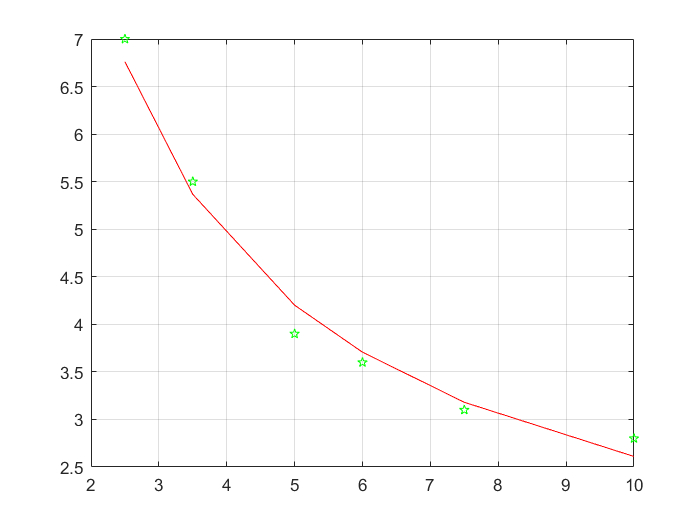


% GRAPH
figure
plot(x, y, 'pg')
hold on
plot(x, f(x), '-r')
hold off
grid

% GRAPH

